# 10주차 — 안정 여유: -1 점에서 얼마나 떨어져 있는가

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

지난 주에는 주파수응답이 **어떻게 생겼는지**를 봤습니다. 오늘은 그 그림으로 **안정한지 아닌지, 그리고 얼마나 여유가 있는지**를 판단합니다.

5주차에서도 안정도를 다뤘습니다. 그때는 극점이 좌반면에 있는지를 봤습니다. 오늘 방법이 그것보다 나은 점은 두 가지입니다.

- **모델이 없어도 된다.** 실험으로 잰 보드 선도만 있으면 판단할 수 있다

- **얼마나 여유가 있는지 숫자로 준다.** 안정한가 아닌가만이 아니라 "얼마나 더 나빠져도 버티는가" 를 알려 준다

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W10_Nyquist_Margin` 폴더 안에 있습니다.

오늘 처음 쓰는 도우미 함수도 하나 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

**개루프의 크기가 **$1$** 이고 위상이 **$-180^\circ$** 이면 폐루프가 불안정해진다. 그 점에서 얼마나 떨어져 있는가가 곧 안정 여유다.**

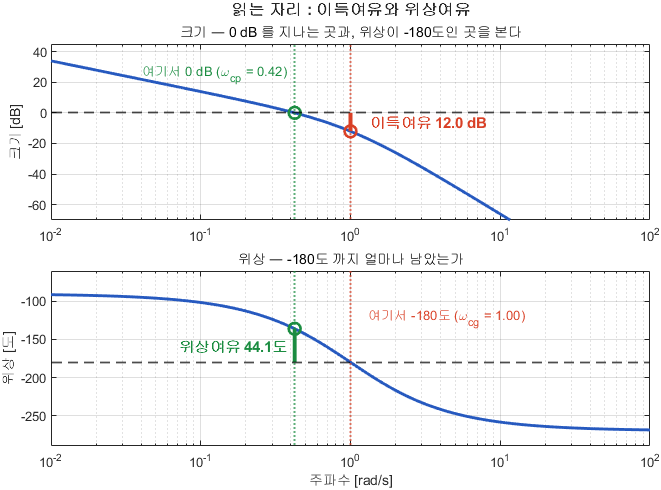

보드 선도에서 이득여유와 위상여유를 읽는 자리

**그림 파일** `w10_margin_read.png` — `common/dg_margin.m` 의 `dg_margin` · 다시 만들려면 `make_figures('w10_margin_read')`

**만드는 곳** — `common/dg_margin.m` (`make_figures('w10_margin_read')`). 명령창에서 `dg_margin(0.5/(s*(s+1)^2))` 처럼 다른 시스템으로 불러도 됩니다 **직접 해 보려면** — `W10_01_nyquist_margin.m` 의 **3절**이 같은 값을 `margin` 으로 뽑아 표로 찍어 줍니다

그림 해석 — **이 표를 그대로 읽으면 3절 설명이 됩니다**

학생들이 가장 많이 틀리는 것이 이 **교차**입니다. $-180^\circ$ 를 아래에서 찾아 **위에서** 읽으면 GM, $0$ dB 를 위에서 찾아 **아래에서** 읽으면 PM 입니다.

오늘의 계단

- **1절** 왜 하필 크기 $1$, 위상 $-180^\circ$ 인가

- **2절** 나이퀴스트 선도 — 둘을 한 평면에

- **3절** 이득여유와 위상여유를 읽는 순서

- **4절** 여유가 얼마면 충분한가

- **5절** 시간영역 사양과의 번역

- **6절** Simulink 모델에서 여유 뽑아내기

## 0-1. 가장 작은 예부터 — 마이크와 스피커

강의실에서 마이크를 스피커 쪽으로 돌리면 "삐-" 하고 울립니다. 이것이 바로 오늘의 주제입니다.

무슨 일이 일어난 것인가.

- 스피커 소리가 마이크로 **되돌아온다** (피드백 루프가 생겼다)

- 어떤 특정 주파수에서 **소리가 줄지 않고 그대로 돌아온다** (크기 $= 1$)

- 그리고 그 주파수에서 **위상이 딱 맞아떨어진다** (위상 $= -180^\circ$)

그러면 그 주파수의 소리가 스스로 유지되고 커집니다. 그것이 하울링입니다.

마이크를 멀리 두면 안 울립니다. 되돌아오는 소리가 작아져 **크기 조건을 못 맞추기 때문**입니다. 그 여유가 곧 **이득여유**입니다.

## 0-2. 왜 하필 $-1$ 인가 — 신호를 따라가 보면

공식으로 외우기 전에 **신호가 한 바퀴 도는 것**을 직접 보십시오.

되먹임 루프에서 오차 $e$ 는 $L$ 을 지나 되돌아와 다시 $e$ 에 더해집니다. 그런데 되먹임은 **빼기**이므로, 돌아온 신호의 위상이 $-180^\circ$ 라면 빼기와 뒤집힘이 겹쳐 **원래 신호와 같은 부호로 더해집니다.**

그때 크기가 $1$ 보다 크면 매 바퀴마다 커지고, 작으면 매 바퀴마다 줄어듭니다.

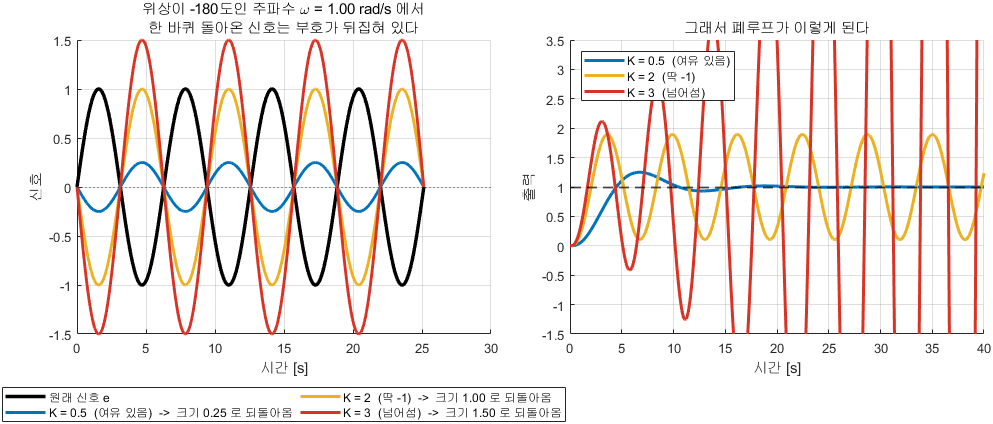

-180도 주파수에서 한 바퀴 돌아온 신호의 크기가 전부를 정한다

**그림 파일** `w10_why_minus1.png` — `make_figures.m` 의 `fig_w10_why_minus_one` · 다시 만들려면 `make_figures('w10_why_minus1')`

**만드는 곳** — `make_figures.m` 의 `fig_w10_why_minus_one` **직접 바꿔 보려면** — 함수 안의 `Ks = [0.5 2 3]` 에 $1.0$ 을 추가해 보십시오

그림 해석

**왼쪽의 진폭 하나가 오른쪽의 운명을 정합니다.** 그 진폭이 정확히 $|L(j\omega)|$ 이고, 그것이 $1$ 이 되는 자리가 $-1$ 점입니다.

## 1. 불안정의 조건

단위 피드백 폐루프는 이렇습니다.


$$T(s) = \frac{L(s)}{1 + L(s)}$$


분모가 $0$ 이 되는 $s$ 가 폐루프 극점이므로


$$1 + L(s) = 0 \qquad \Rightarrow \qquad L(s) = -1$$


$s = j\omega$ 로 놓고 읽으면 이렇습니다.


$$|L(j\omega)| = 1 \quad\text{이면서}\quad \angle L(j\omega) = -180^\circ$$


**왜 이것이 위험한가**

- 위상 $-180^\circ$ 는 되돌아오는 신호가 **뒤집혀 온다**는 뜻이다

- 피드백에서 한 번 더 빼면 결국 **더해지는** 셈이 된다

- 거기에 크기까지 $1$ 이면 줄지도 늘지도 않고 **계속 돈다**

이 두 조건을 동시에 만족하는 주파수가 있으면 그 주파수로 진동합니다.

## 1-1. 숫자로 확인

강의자료 6장의 표준 예제로 확인합니다.


$$L(s) = \frac{K}{s\,(s+1)^2}$$


G = 1/(s*(s+1)^2);
fprintf('=== K 를 키우면 ===\n');

=== K 를 키우면 ===


fprintf('     K     폐루프 극점 실수부 최댓값    상태\n');

     K     폐루프 극점 실수부 최댓값    상태


fprintf('   ------  ------------------------  --------\n');

   ------  ------------------------  --------


for K = [0.5 1 2 3]
    mx = max(real(pole(feedback(K*G,1))));
    if mx < -1e-6,          st = '안정';
    elseif abs(mx) < 1e-6,  st = '경계';
    else,                   st = '불안정';
    end
    fprintf('   %6.1f  %24.4f  %8s\n', K, mx, st);
end

      0.5                   -0.2174        안정
      1.0                   -0.1226        안정
      2.0                    0.0000        경계
      3.0                    0.0873       불안정


fprintf('\n');
fprintf('  이 시스템은 K = 2 가 안정 한계입니다.\n');

  이 시스템은 K = 2 가 안정 한계입니다.


fprintf('  5주차에서 Routh 표로 구했던 임계이득과 같은 값입니다.\n\n');

  5주차에서 Routh 표로 구했던 임계이득과 같은 값입니다.



## 2. 나이퀴스트 선도

보드 선도는 크기와 위상을 **따로** 그렸습니다. 나이퀴스트 선도는 둘을 **한 평면에** 그립니다.

$\omega$ 를 훑으며 복소수 $L(j\omega)$ 를 복소평면에 찍는 것뿐입니다. 그러면 "$-1$ 이 되는가" 를 눈으로 볼 수 있습니다.

보드 선도와 나이퀴스트 선도는 **같은 정보를 다르게 그린 것**입니다.

그래서 "크기 $1$, 위상 $-180^\circ$" 라는 두 조건이 나이퀴스트 선도에서는 **점 하나**($-1$)가 됩니다. 이것이 오늘 이 그림을 쓰는 이유입니다.

## 2-0. `nyquist` — 오늘의 새 명령

- **원리** — $\omega$ 를 $-\infty$ 에서 $+\infty$ 까지 훑으며 복소수 $L(j\omega)$ 를 복소평면에 찍는다

- **입력** — **개루프** 전달함수 $L$. `margin` 과 같습니다

- **출력** — 받지 않으면 그림. `[re, im] = nyquist(L, w)` 로 값도 받을 수 있다

주의 네 가지

- **폐루프를 넣으면 안 됩니다.** $-1$ 점 판정은 개루프에 대한 것입니다

- 그림에 `-1` 자리를 표시해 주지 않습니다. `hold on` 하고 직접 찍으십시오

- $\omega$ 가 음수인 쪽까지 그리므로 **곡선이 실축 기준으로 대칭**입니다. 두 겹으로 보이는 것이 정상입니다

- **원점에 극점(적분기)이 있으면 곡선이 무한대로 날아가** 그림이 깨집니다. 그때는 `common/` 의 `nyquist1` 을 쓰십시오. $j\omega$ 축을 살짝 우회해 그려 줍니다

값을 받아 쓰는 예 — $-1$ 점까지의 **최단 거리**를 재 봅니다. 이 거리가 곧 "얼마나 아슬아슬한가" 입니다.

s = tf('s');
G_ex = 1/(s*(s+1)^2);
w_ex = logspace(-1, 1, 2000);
[re_ex, im_ex] = nyquist(0.5*G_ex, w_ex);
re_ex = squeeze(re_ex);  im_ex = squeeze(im_ex);
dist  = min(hypot(re_ex + 1, im_ex));
fprintf('=== nyquist 로 값 받기 ===\n');

=== nyquist 로 값 받기 ===


fprintf('  K = 0.5 일 때 궤적과 -1 점의 최단 거리 : %.3f\n', dist);

  K = 0.5 일 때 궤적과 -1 점의 최단 거리 : 0.542


fprintf('  (이 거리가 작을수록 불안정에 가깝습니다.\n');

  (이 거리가 작을수록 불안정에 가깝습니다.


fprintf('   5절에서 배울 감도 최대값과 %.3f = 1/%.2f 로 이어집니다)\n\n', ...
        dist, 1/dist);

   5절에서 배울 감도 최대값과 0.542 = 1/1.84 로 이어집니다)



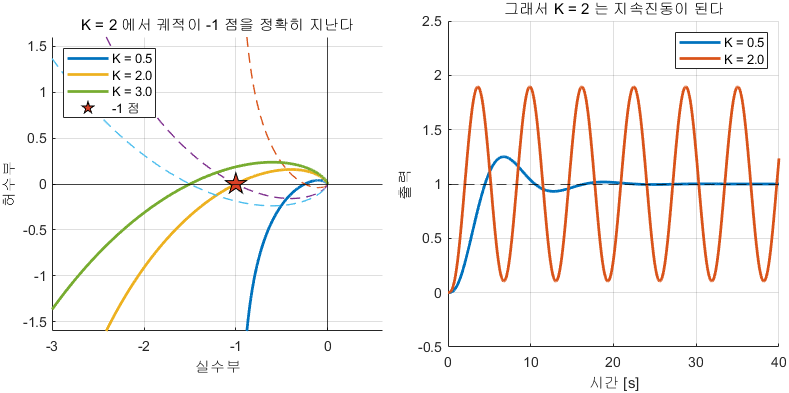

K = 2 에서 궤적이 -1 점을 정확히 지난다

**그림 파일** `w10_nyquist_K.png` — `make_figures.m` 의 `fig_nyquist_K` · 다시 만들려면 `make_figures('w10_nyquist_K')`

**만드는 곳** — `make_figures.m` 의 `fig_nyquist_K` **직접 바꿔 보려면** — `W10_01_nyquist_margin.m` 의 **2절**에서 `Ks` 를 바꿔 실행. `nyquist1` 을 쓰면 적분기가 있어도 깔끔하게 그려 줍니다

그림 해석

**보드 선도의 두 그림을 한 장으로 접은 것**이 나이퀴스트 선도입니다. 원점에서의 거리가 크기, 각도가 위상입니다. 그래서 "크기 $1$, 위상 $-180^\circ$" 가 이 그림에서는 **점 하나**가 됩니다.

## 2-0-1. 그런데 왜 $\omega$ 를 음수까지 훑는가 — 나이퀴스트 경로

앞 절의 주의에서 "곡선이 실축 기준으로 대칭이라 두 겹으로 보인다" 고 했습니다. 그것이 왜 그런지, 그리고 애초에 왜 그렇게 그리는지 짚고 갑니다. **이 절을 건너뛰면 다음 절의 판정법이 마술처럼 보입니다.**

우리가 알고 싶은 것은 **폐루프 극점이 우반면에 있는가**입니다. 폐루프 극점은 $1 + L(s) = 0$ 의 근이므로, 결국 **"**$1+L(s)$** 가 우반면에서 **$0$** 이 되는 곳이 있는가"** 를 묻는 것입니다.

복소해석에는 이런 질문에 답하는 도구가 있습니다. **어떤 닫힌 길을 따라 함수값이 원점을 몇 바퀴 도는지 세면, 그 길 안에 영점과 극점이 각각 몇 개 있는지 알 수 있습니다.** 이것이 **편각원리**입니다.

그래서 **우반면 전체를 감싸는 닫힌 길**을 만듭니다. 그 길이 두 부분입니다.

- **허수축** — $s = j\omega$ 로 $\omega$ 를 $-\infty$ 에서 $+\infty$ 까지

- **무한대 반원** — 오른쪽을 크게 돌아 출발점으로 되돌아온다

이 닫힌 길을 **나이퀴스트 경로**라고 합니다.

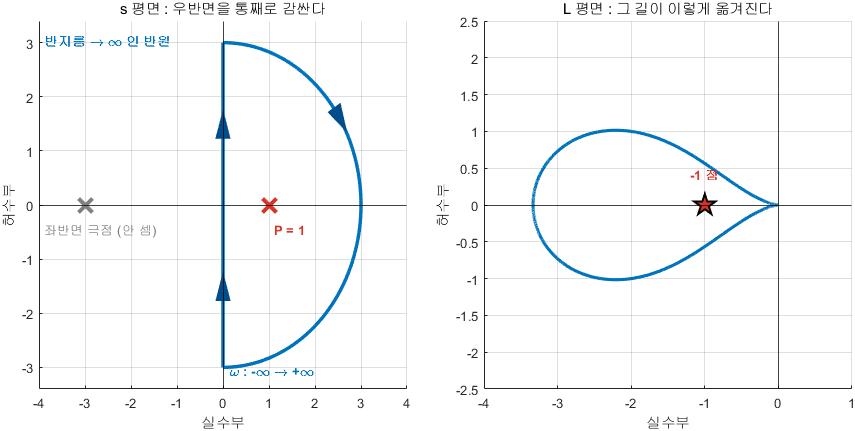

우반면을 감싸는 닫힌 길을 L 로 옮긴 것이 나이퀴스트 선도다

**그림 파일** `w10_contour.png` — `make_figures.m` 의 `fig_w10_contour` · 다시 만들려면 `make_figures('w10_contour')`

**만드는 곳** — `make_figures.m` 의 `fig_w10_contour` **직접 확인해 보려면** — `W10_01_nyquist_margin.m` 의 **2절**

그림 해석

마지막 줄이 "두 겹으로 보인다" 의 정체입니다. 우리가 실제로 계산하는 것은 $\omega > 0$ 쪽 절반뿐이고, 나머지 절반은 **거울에 비친 것**입니다.

그리고 원점에 극점(적분기)이 있으면 그 점이 경로 위에 놓여 버립니다. 편각원리는 경로 **위에** 극점이 있으면 쓸 수 없으므로, 그때는 원점을 아주 작은 반원으로 살짝 우회합니다. `common/nyquist1.m` 이 그 우회를 대신해 줍니다.

## 2-1. 나이퀴스트 판정

바탕은 복소해석의 **편각원리**입니다. 결론만 쓰면 이렇습니다.


$$Z = N + P$$


- $Z$ — 우반면에 있는 **폐루프** 극점 개수 ($0$ 이라야 안정)

- $N$ — 나이퀴스트 선도가 $-1$ 점을 **시계 방향으로** 감은 횟수

- $P$ — 우반면에 있는 **개루프** 극점 개수

실무에서 쓰는 규칙은 대개 한 줄로 줄어듭니다.

**개루프가 안정하면(**$P = 0$**), 나이퀴스트 선도가 **$-1$** 을 감지 않아야 안정하다.**

그러면 왜 굳이 $P$ 까지 따지는 판정을 배우는가 — **개루프가 이미 불안정한 시스템**이 실제로 있기 때문입니다. 거꾸로 선 진자가 그 예이고, 그런 시스템은 오히려 **이득을 충분히 키워야** 안정해집니다.

Gu = 1/((s-1)*(s+3));
fprintf('=== 개루프가 불안정한 경우 : G = 1/((s-1)(s+3)) ===\n');

=== 개루프가 불안정한 경우 : G = 1/((s-1)(s+3)) ===


fprintf('  개루프 극점 %s -> 우반면 극점 P = 1\n', mat2str(round(pole(Gu).',3)));

  개루프 극점 [-3 1] -> 우반면 극점 P = 1


fprintf('     K     폐루프 우반면 극점 Z    상태\n');

     K     폐루프 우반면 극점 Z    상태


fprintf('   ------  ---------------------  --------\n');

   ------  ---------------------  --------


for K = [1 3 5 10]
    Z = sum(real(pole(feedback(K*Gu,1))) > 1e-9);
    if Z == 0, st = '안정'; else, st = '불안정'; end
    fprintf('   %6.1f  %21d  %8s\n', K, Z, st);
end

      1.0                      1       불안정
      3.0                      0        안정
      5.0                      0        안정
     10.0                      0        안정


fprintf('\n');
fprintf('  이득을 키워야 안정해집니다. 상식이 항상 맞지는 않습니다.\n\n');

  이득을 키워야 안정해집니다. 상식이 항상 맞지는 않습니다.



## 2-1-1. $N$ 을 실제로 세어 본다

위 표는 `pole(feedback(...))` 로 **답을 미리 본 것**입니다. 이제 그림만 보고 $N$ 을 세어 같은 답이 나오는지 확인합니다. **이것이 나이퀴스트 판정을 실제로 쓰는 방법입니다.**

세는 요령

- $-1$ 점에서 아무 방향으로나 **반직선**을 하나 긋는다 (아래쪽이 편하다)

- 곡선이 그 반직선과 만나는 횟수를 센다

- **시계 방향**으로 지나가면 $+1$, **반시계 방향**으로 지나가면 $-1$

- 그 합이 $N$ 이다

반직선의 방향은 아무래도 좋습니다. 답이 같게 나옵니다. 곡선이 $-1$ 을 아예 안 감싸면 $N=0$ 입니다.

이 예제는 $G(s) = \frac{K}{(s-1)(s+3)}$ 이고 $P = 1$ 입니다. $\omega = 0$ 에서 $L(0) = -K/3$ 이므로 곡선은 **음의 실축에서 출발**합니다. 그러므로 $-1$ 이 곡선 안에 들어오는지는 $K/3$ 이 $1$ 보다 큰지로 갈립니다.

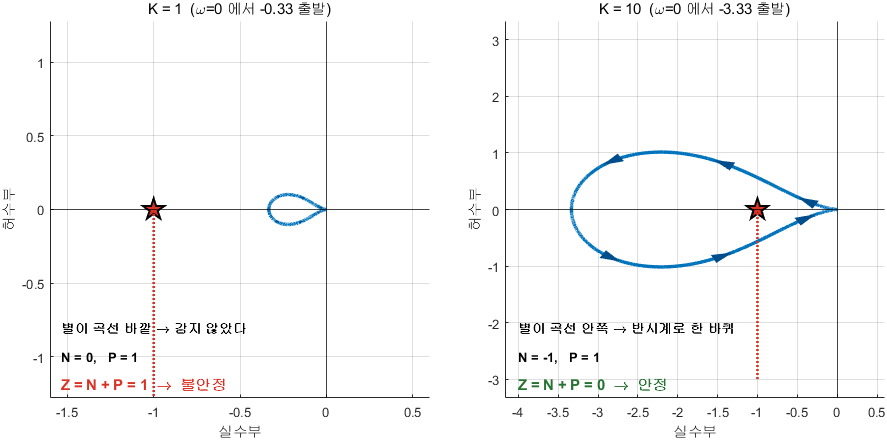

-1 점이 곡선 안에 있는지가 갈랐다

**그림 파일** `w10_encircle.png` — `make_figures.m` 의 `fig_w10_encircle` · 다시 만들려면 `make_figures('w10_encircle')`

**만드는 곳** — `make_figures.m` 의 `fig_w10_encircle` **직접 확인해 보려면** — `W10_01_nyquist_margin.m` 의 **2-1절**에서 `K` 를 $2.9$ 와 $3.1$ 로 바꿔 보십시오. 경계가 정확히 $K=3$ 입니다

그림 해석

**개루프가 불안정하면 **$-1$** 을 "피하는" 것이 아니라 "제대로 감아야" 합니다.** $P=0$ 일 때의 실무 규칙을 그대로 외워 두면 이런 경우에 정반대로 판단하게 됩니다.

아래 코드가 곡선의 왼쪽 끝만 보고 판정합니다. 이 예제는 곡선이 음의 실축에서 출발해 한 바퀴 도는 단순한 모양이라 $-K/3$** 이 **$-1$** 보다 왼쪽인가**만 보면 됩니다.

fprintf('=== 그림만 보고 판정하기 ===\n');

=== 그림만 보고 판정하기 ===


fprintf('  %-6s %-12s %-6s %-6s %-6s %s\n', 'K', 'L(0)=-K/3', 'N', 'P', 'Z', '판정');

  K      L(0)=-K/3    N      P      Z      판정


for K = [1 2.9 3.1 10]
    L0 = -K/3;
    if L0 < -1, N = -1; else, N = 0; end
    Z = N + 1;
    if Z == 0, st = '안정'; else, st = '불안정'; end
    Zreal = sum(real(pole(feedback(K*Gu,1))) > 1e-9);
    fprintf('  %-6.1f %-12.3f %-6d %-6d %-6d %s   (실제 Z = %d)\n', ...
            K, L0, N, 1, Z, st, Zreal);
end

  1.0    -0.333       0      1      1      불안정   (실제 Z = 1)
  2.9    -0.967       0      1      1      불안정   (실제 Z = 1)
  3.1    -1.033       -1     1      0      안정   (실제 Z = 0)
  10.0   -3.333       -1     1      0      안정   (실제 Z = 0)


fprintf('  --> 그림으로 센 Z 와 실제 Z 가 모두 같습니다.\n');

  --> 그림으로 센 Z 와 실제 Z 가 모두 같습니다.


fprintf('      경계는 -K/3 = -1, 즉 K = 3 입니다.\n\n');

      경계는 -K/3 = -1, 즉 K = 3 입니다.



## 3. 이득여유와 위상여유

"$-1$ 점에서 얼마나 떨어져 있는가" 를 두 방향으로 나눠 잰 것입니다.

- **이득여유 (GM)** — 위상이 $-180^\circ$ 인 주파수 $\omega_{cg}$ 에서, 크기를 **몇 배** 더 키우면 $1$ 이 되는가

- **위상여유 (PM)** — 크기가 $1$ ($0$ dB) 인 주파수 $\omega_{cp}$ 에서, 위상이 $-180^\circ$ 까지 **몇 도** 남았는가

**읽는 순서를 반드시 기억하십시오.** 학생들이 가장 많이 혼동하기 쉬운 부분입니다.

- 아래 위상 그림에서 $-180^\circ$ 인 곳을 찾는다 $\rightarrow$ $\omega_{cg}$

- 그 주파수에서 **위 크기 그림**을 본다 $\rightarrow$ 이득여유

- 위 크기 그림에서 $0$ dB 인 곳을 찾는다 $\rightarrow$ $\omega_{cp}$

- 그 주파수에서 **아래 위상 그림**을 본다 $\rightarrow$ 위상여유

즉 **한 그림에서 찾고 다른 그림에서 읽습니다.**

fprintf('=== margin 이 주는 값 ===\n');

=== margin 이 주는 값 ===


fprintf('     K      GM[배]   GM[dB]    PM[도]     wcg      wcp\n');

     K      GM[배]   GM[dB]    PM[도]     wcg      wcp


fprintf('   ------  -------  -------  --------  -------  -------\n');

   ------  -------  -------  --------  -------  -------


ws = warning('off','Control:analysis:MarginUnstable');
for K = [0.2 0.5 1 2 3]
    [gm, pm, wcg, wcp] = margin(K*G);
    fprintf('   %6.1f  %7.3f  %7.2f  %8.2f  %7.3f  %7.3f\n', ...
            K, gm, 20*log10(gm), pm, wcg, wcp);
end

      0.2   10.000    20.00     68.17    1.000    0.193
      0.5    4.000    12.04     44.06    1.000    0.424
      1.0    2.000     6.02     21.39    1.000    0.682
      2.0    1.000     0.00      0.00    1.000    1.000
      3.0    0.667    -3.52    -11.01    1.000    1.213


warning(ws);
fprintf('\n');
fprintf('  읽는 법\n');

  읽는 법


fprintf('    K 를 키우면 크기 곡선이 통째로 위로 올라갑니다.\n');

    K 를 키우면 크기 곡선이 통째로 위로 올라갑니다.


fprintf('    그래서 이득여유가 정확히 K 에 반비례합니다.\n');

    그래서 이득여유가 정확히 K 에 반비례합니다.


fprintf('    K = 2 에서 GM = 1 배 (0 dB), PM = 0 도. 안정 한계입니다.\n\n');

    K = 2 에서 GM = 1 배 (0 dB), PM = 0 도. 안정 한계입니다.



## 3-1. `margin` — 오늘의 새 명령

명령 정리

- **원리** — 크기가 $0$ dB 를 지나는 곳과 위상이 $-180^\circ$ 를 지나는 곳을 찾는다

- **입력** — **개루프** 전달함수 $L$. 폐루프를 넣으면 안 된다

- **출력** — `[Gm, Pm, Wcg, Wcp]`

주의 세 가지

- `Gm` 은 **배율**이다. dB 로 보려면 `20*log10(Gm)` 을 직접 해야 한다

- 여유가 `Inf` 로 나오는 것은 "무한히 안정" 이 아니라 **그 조건을 만나는 주파수가 없다**는 뜻이다

- 출력을 안 받고 `margin(L)` 만 부르면 그림을 그린다

예제

L1 = 0.5*G;
[gm, pm, wcg, wcp] = margin(L1);
fprintf('=== margin 예제 ===\n');

=== margin 예제 ===


fprintf('  L = 0.5/(s(s+1)^2)\n');

  L = 0.5/(s(s+1)^2)


fprintf('  GM = %.3f 배 = %.2f dB   (wcg = %.3f rad s^-1)\n', gm, 20*log10(gm), wcg);

  GM = 4.000 배 = 12.04 dB   (wcg = 1.000 rad s^-1)


fprintf('  PM = %.2f 도             (wcp = %.3f rad s^-1)\n\n', pm, wcp);

  PM = 44.06 도             (wcp = 0.424 rad s^-1)



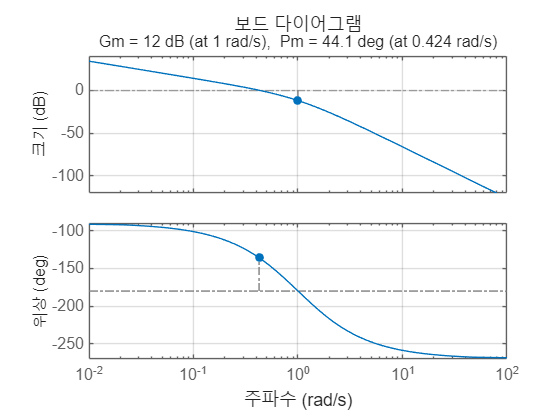

margin(L1); grid on;

## 4. 여유가 얼마면 충분한가

실무 기준은 이렇습니다.

- 이득여유 $6$ dB 이상 (약 $2$ 배)

- 위상여유 $30^\circ \sim 60^\circ$

**왜 여유가 필요한가** — 모델은 반드시 틀리기 때문입니다.

- 부품이 노후하면 이득이 변한다

- 온도가 바뀌면 시정수가 변한다

- 계산 시간, 통신 지연, 센서 처리 시간이 위상을 깎는다

여유란 **그만큼 틀려도 버틴다** 는 보증입니다.

## 4-1. 위상여유를 시간지연으로 바꿔 읽기

위상여유는 추상적으로 느껴지지만, **시간지연으로 바꾸면 아주 구체적**입니다.

시간지연 $\tau$ 의 주파수응답은


$$e^{-j\omega\tau}$$


크기는 언제나 $1$ 입니다. **크기 곡선을 전혀 건드리지 않습니다.** 위상만 $-\omega\tau$ 만큼 깎습니다.

따라서 교차주파수 $\omega_{cp}$ 에서 위상여유를 다 까먹는 지연은


$$\tau_{max} = \frac{PM\,[\mathrm{rad}]}{\omega_{cp}}$$


즉 **"우리 설계는 몇 초의 지연까지 견딘다"** 를 숫자로 말할 수 있습니다. 통신 지연이나 계산 시간을 다룰 때 실무에서 그대로 쓰는 식입니다.

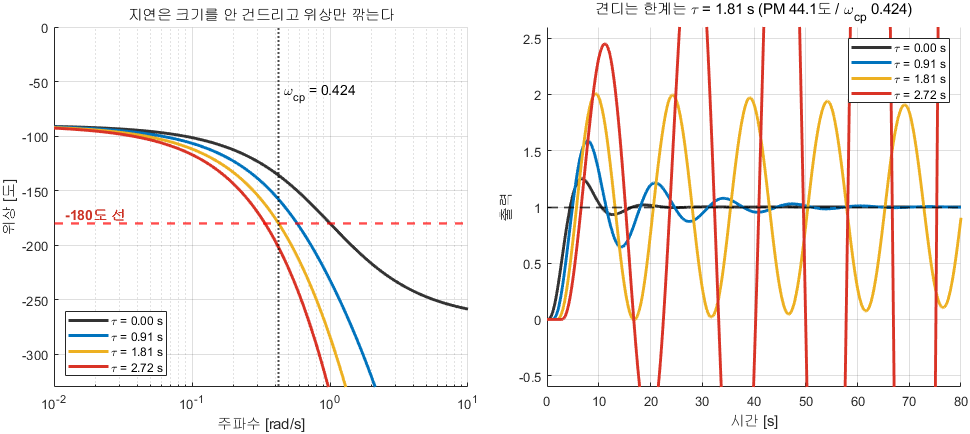

지연은 크기를 안 건드리고 위상만 깎는다

**그림 파일** `w10_delay.png` — `make_figures.m` 의 `fig_w10_delay` · 다시 만들려면 `make_figures('w10_delay')`

**만드는 곳** — `make_figures.m` 의 `fig_w10_delay` **직접 확인해 보려면** — `W10_03_run_simulink.m` 이 Simulink 모델에 `Transport Delay` 를 넣고 같은 실험을 합니다

그림 해석

계산식으로 확인하면 $\tau_{max} = 44.1^\circ \times (\pi/180) / 0.424 = 1.81$ s 입니다. **그림의 노란 곡선이 정확히 그 값에서 안정 한계가 되었습니다.** 위상여유가 추상적으로 느껴질 때 이 변환을 쓰십시오.

fprintf('=== 위상여유를 시간지연으로 ===\n');

=== 위상여유를 시간지연으로 ===


fprintf('     K      PM[도]     wcp      견디는 지연[s]\n');

     K      PM[도]     wcp      견디는 지연[s]


fprintf('   ------  --------  -------  ----------------\n');

   ------  --------  -------  ----------------


for K = [0.2 0.5 1.0]
    [~, pm_, ~, wcp_] = margin(K*G);
    fprintf('   %6.1f  %8.2f  %7.3f  %16.3f\n', K, pm_, wcp_, deg2rad(pm_)/wcp_);
end

      0.2     68.17    0.193             6.170
      0.5     44.06    0.424             1.814
      1.0     21.39    0.682             0.547


fprintf('\n');
fprintf('  읽는 법\n');

  읽는 법


fprintf('    이득을 키우면 견딜 수 있는 지연이 급격히 줄어듭니다.\n');

    이득을 키우면 견딜 수 있는 지연이 급격히 줄어듭니다.


fprintf('    빠른 제어기일수록 지연에 약합니다. 공짜가 없습니다.\n\n');

    빠른 제어기일수록 지연에 약합니다. 공짜가 없습니다.



## 5. 시간영역 사양과의 번역

4주차에서 배운 시간영역 사양과 오늘의 주파수영역 사양은 **같은 것을 다르게 말하는 것**입니다. 서로 번역할 수 있습니다.

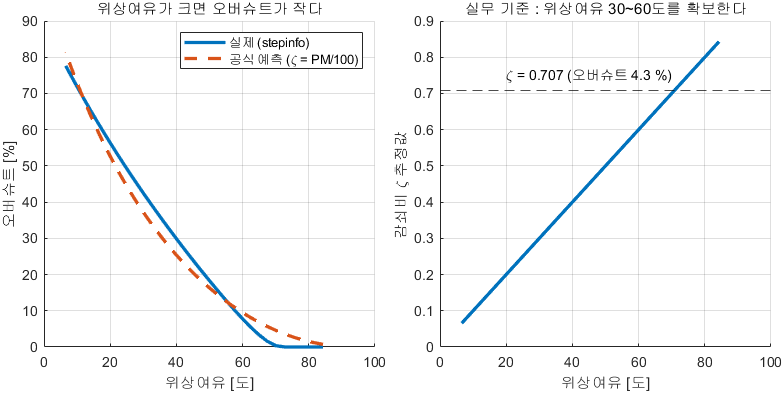

위상여유가 크면 오버슈트가 작다

**그림 파일** `w10_pm_os.png` — `make_figures.m` 의 `fig_pm_os` · 다시 만들려면 `make_figures('w10_pm_os')`

**만드는 곳** — `make_figures.m` 의 `fig_pm_os` **직접 확인해 보려면** — `W10_02_pm_to_time.m` 의 **1절**이 이득을 훑으며 PM 과 실제 오버슈트를 나란히 표로 찍어 줍니다

그림 해석

**외울 것은 **$\zeta \approx PM/100$** 한 줄입니다.** PM $30^\circ$ 면 $\zeta \approx 0.3$ (오버슈트 $37\%$), PM $60^\circ$ 면 $\zeta \approx 0.6$ (오버슈트 $9\%$) 로 어림합니다.

fprintf('=== 위상여유로 오버슈트 짐작하기 ===\n');

=== 위상여유로 오버슈트 짐작하기 ===


fprintf('     K      PM[도]   zeta 추정   공식 OS[%%]   실제 OS[%%]\n');

     K      PM[도]   zeta 추정   공식 OS[%]   실제 OS[%]


fprintf('   ------  --------  ---------  -----------  -----------\n');

   ------  --------  ---------  -----------  -----------


for K = [0.2 0.4 0.6 0.8 1.0]
    [~, pm_] = margin(K*G);
    z  = pm_/100;
    oe = 100*exp(-z*pi/sqrt(1-z^2));
    ii = stepinfo(feedback(K*G,1));
    fprintf('   %6.1f  %8.2f  %9.4f  %11.2f  %11.2f\n', K, pm_, z, oe, ii.Overshoot);
end

      0.2     68.17     0.6817         5.35         1.17
      0.4     50.89     0.5089        15.61        17.31
      0.6     38.20     0.3820        27.29        32.08
      0.8     28.73     0.2873        38.97        44.19
      1.0     21.39     0.2139        50.27        54.35


fprintf('\n');
fprintf('  정확히 맞지는 않습니다. 3차 시스템이라 2차 공식이 어긋납니다.\n');

  정확히 맞지는 않습니다. 3차 시스템이라 2차 공식이 어긋납니다.


fprintf('  그래도 **설계 초기에 짐작하기에는 충분합니다.**\n');

  그래도 **설계 초기에 짐작하기에는 충분합니다.**


fprintf('  설계를 마치면 반드시 stepinfo 로 검증해야 합니다.\n\n');

  설계를 마치면 반드시 stepinfo 로 검증해야 합니다.



## 5-1. 대역폭 — 빠르기의 주파수영역 표현

대역폭이란 폐루프 크기가 $-3$ dB 로 떨어지는 주파수입니다. "이 주파수까지는 지령을 따라간다" 는 뜻이므로 곧 **빠르기**입니다.

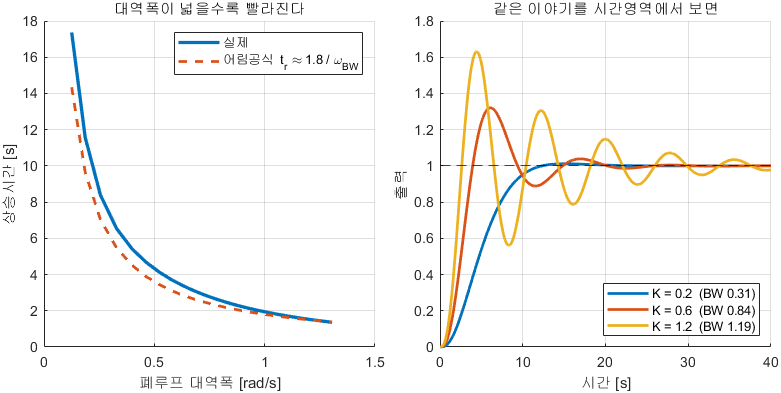

대역폭이 넓을수록 빠르다

**그림 파일** `w10_bw_speed.png` — `make_figures.m` 의 `fig_bw_speed` · 다시 만들려면 `make_figures('w10_bw_speed')`

**만드는 곳** — `make_figures.m` 의 `fig_bw_speed` **직접 확인해 보려면** — `W10_02_pm_to_time.m` 의 **2절**

그림 해석

왼쪽만 보면 "대역폭을 넓히면 좋다" 로 읽힙니다. **오른쪽을 함께 보십시오.** 대역폭을 넓히려고 이득을 키우면 위상여유가 깎여 오버슈트가 커집니다. 여기서도 공짜가 없습니다.

fprintf('=== 대역폭과 시간응답 ===\n');

=== 대역폭과 시간응답 ===


fprintf('     K     대역폭[rad s^-1]   상승시간[s]   1.8 나누기 BW\n');

     K     대역폭[rad s^-1]   상승시간[s]   1.8 나누기 BW


fprintf('   ------  -----------------  -----------  ---------------\n');

   ------  -----------------  -----------  ---------------


for K = [0.2 0.5 1.0 1.4]
    T = feedback(K*G, 1);
    ii = stepinfo(T);  b = bandwidth(T);
    fprintf('   %6.1f  %17.3f  %11.2f  %15.2f\n', K, b, ii.RiseTime, 1.8/b);
end

      0.2              0.313         6.86             5.75
      0.5              0.750         2.77             2.40
      1.0              1.094         1.73             1.64
      1.4              1.269         1.42             1.42


fprintf('\n');

## 5-2. 근본적인 맞바꿈 — 감도함수

두 전달함수를 함께 봅니다. 그런데 그 전에 **잡음이 어디로 들어오는지**를 그림에서 확인해야 합니다. 외란과 들어오는 자리가 다릅니다.

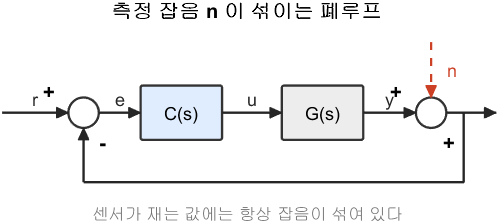

측정 잡음 n 은 출력 쪽 되먹임 경로로 들어온다

**그림 파일** `loop_noise.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_noise')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('noise', ...)` 로 부릅니다

그림 해석

이제 두 전달함수를 유도합니다. 신호를 따라가면 됩니다.


$$e = r - (y + n), \qquad y = L\,e$$


둘째를 첫째에 넣고 $y$ 를 한쪽으로 모읍니다.


$$y = L\,(r - y - n) \;\Rightarrow\; (1+L)\,y = L\,r - L\,n \;\Rightarrow\; y = \frac{L}{1+L}\,r - \frac{L}{1+L}\,n$$


그리고 오차는 (1주차 · 5주차와 같은 방법으로)


$$e = \frac{1}{1+L}\,r$$


여기 나온 두 덩어리에 이름을 붙인 것이 전부입니다.


$$S(s) = \frac{1}{1+L}, \qquad T(s) = \frac{L}{1+L}$$


$T$ 의 이름에 "상보" 가 붙은 이유는 한 줄이면 나옵니다. 두 분수의 **분모가 같으므로 그냥 더하면** 됩니다.


$$S + T = \frac{1}{1+L} + \frac{L}{1+L} = \frac{1 + L}{1+L} = 1$$



$$S(j\omega) + T(j\omega) = 1 \qquad \text{(모든 주파수에서)}$$


**이것이 제어의 근본적인 맞바꿈입니다.** 둘 다 작게 만들 수는 없습니다. $S$ 를 $0.01$ 로 만들면 그 주파수에서 $T$ 는 자동으로 $0.99$ 가 됩니다. 우리가 고를 수 있는 것은 **어느 주파수에서 어느 쪽을 작게 할 것인가**뿐입니다.

실무의 해법은 **주파수를 나눠 쓰는 것**입니다.

- 저주파에서 $S$ 를 작게 $\rightarrow$ 외란 억제, 정상상태 오차 감소

- 고주파에서 $T$ 를 작게 $\rightarrow$ 측정 잡음 억제

- 교차주파수 근처는 어쩔 수 없다. 그래서 **교차주파수를 어디에 둘 것인가**가 설계다

이득을 키우면 저주파의 $|S|$ 는 좋아지는데 교차주파수 근처의 봉우리가 솟습니다. 그 봉우리가 위상여유와 정확히 반대로 움직입니다.

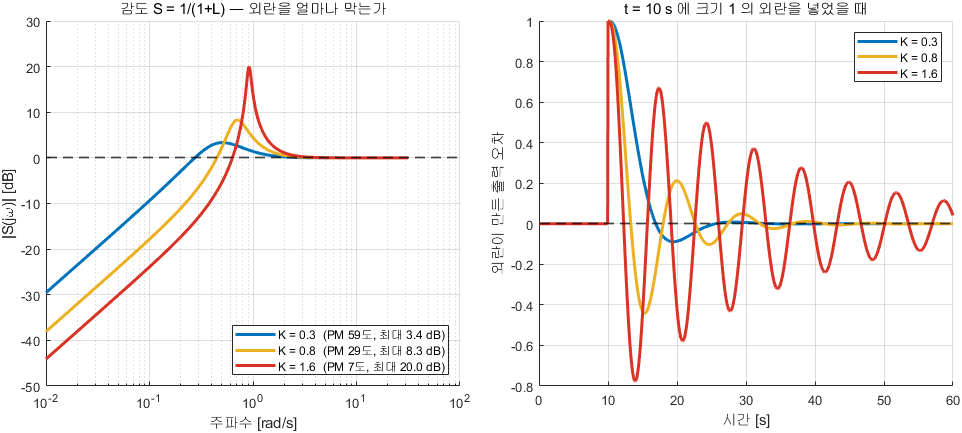

감도의 봉우리와 위상여유는 같은 이야기다

**그림 파일** `w10_sensitivity.png` — `make_figures.m` 의 `fig_w10_sensitivity` · 다시 만들려면 `make_figures('w10_sensitivity')`

**만드는 곳** — `make_figures.m` 의 `fig_w10_sensitivity` **직접 바꿔 보려면** — 함수 안의 `Ks = [0.3 0.8 1.6]` 을 바꿔 실행

그림 해석

**왼쪽 그림의 봉우리가 오른쪽 그림의 진동입니다.** $|S|$ 를 저주파에서 낮추려고 이득을 키우면, 그 대가로 교차주파수 근처에서 봉우리가 솟습니다. 봉우리를 $6$ dB ($2$ 배) 이하로 두라는 것이 실무 기준입니다.

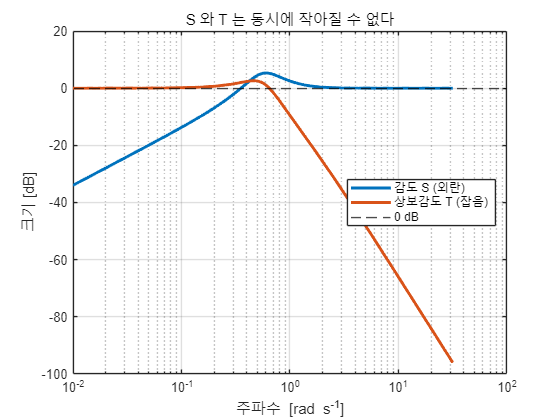

Lx = 0.5*G;  Sx = 1/(1+Lx);  Tx = feedback(Lx,1);
w  = logspace(-2, 1.5, 400);
semilogx(w, 20*log10(squeeze(abs(freqresp(Sx,w)))), 'LineWidth', 2.2); hold on; grid on;
semilogx(w, 20*log10(squeeze(abs(freqresp(Tx,w)))), 'LineWidth', 2.2);
yline(0,'k--');
xlabel('주파수 [rad s^{-1}]'); ylabel('크기 [dB]');
legend('감도 S (외란)', '상보감도 T (잡음)', '0 dB', 'Location','east');
title('S 와 T 는 동시에 작아질 수 없다');

## 6. Simulink 모델에서 여유 뽑아내기

실제 현장에서 모델은 전달함수로 오지 않습니다. **블록선도로 옵니다.** 비선형 블록이 섞여 있고 서브시스템이 여러 겹입니다.

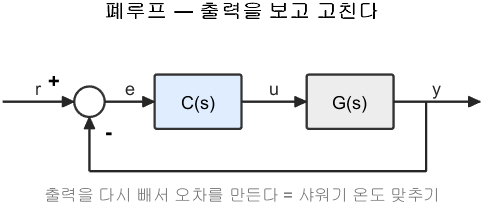

선형화의 대상은 이런 폐루프다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('closed', ...)` 로 부릅니다 **직접 해 보려면** — `W10_03_run_simulink.m` 이 `W10_Margin_Check.slx` 에서 이 루프를 잘라 개루프를 뽑습니다

그림 해석 — **오늘은 "어디를 자를 것인가" 를 정하는 그림입니다**

`margin` 은 **개루프** 를 받습니다. 그래서 Simulink 모델에서도 반드시 루프를 끊어 $L$ 을 만든 뒤에 여유를 재야 합니다. 폐루프를 넣으면 엉뚱한 값이 나옵니다.

이때 쓰는 것이 **선형화**입니다. 절차는 두 줄입니다.

- `linio` 로 **어디를 자를 것인가**를 지정한다 (루프를 끊어야 개루프가 된다)

- `linearize` 로 그 두 점 사이의 전달함수를 얻는다

`linio` — **자를 자리를 표시하는 명령**

- **하는 일** — 모델의 어느 블록 어느 포트를 입력/출력으로 볼지 정한다

- **입력** — `linio('모델/블록이름', 포트번호, 종류)`. 종류는 `'openinput'`(여기서 끊고 넣는다), `'openoutput'`(여기서 끊고 본다) 등

- **출력** — 선형화 지점 객체. 여러 개를 배열로 묶어 `linearize` 에 준다

`linearize` — **실제로 선형화하는 명령**

- **하는 일** — 지정한 두 점 사이를 수치적으로 미분해 상태공간 모델을 만든다

- **입력** — `linearize('모델이름', io)`

- **출력** — `ss` 객체. 그대로 `margin`, `bode` 에 넣으면 된다

주의

- 자르는 종류를 `'input'`/`'output'`(끊지 않음)으로 주면 **폐루프**가 나옵니다. 개루프를 원하면 반드시 `open` 이 붙은 것을 쓰십시오

- 모델이 **평형점에 있어야** 제대로 된 선형화가 나옵니다

## 6-1. 함정 — `linearize` 는 기본적으로 시간지연을 근사한다

4-1절에서 위상여유를 시간지연으로 바꿔 읽었습니다. 그런데 Simulink 모델에 `Transport Delay` 블록을 넣고 그대로 `linearize` 하면 **지연이 결과에 반영되지 않습니다.**

기본 설정이 지연을 유리수 함수로 근사(파데 근사)하는데, 차수가 $0$ 이면 아예 무시해 버리기 때문입니다.

실제로 이 과목을 만들 때 겪은 일입니다 — 지연을 $0$ 초에서 $1$ 초까지 바꿔 가며 `linearize` 를 불렀는데 **위상여유가 **$44.06^\circ$** 로 꼼짝도 안 했습니다.**

`linearizeOptions` — **그 설정을 바꾸는 명령**

- **하는 일** — 선형화 방식을 정하는 옵션 묶음을 만든다

- **입력** — 이름-값 쌍. 오늘 쓰는 것은 `'UseExactDelayModel'`

- **출력** — 옵션 객체. `linearize(모델, io, opt)` 처럼 세 번째 인자로 준다

쓰는 법은 한 줄입니다.

`opt = linearizeOptions('UseExactDelayModel', 'on');`

이렇게 하면 지연을 근사하지 않고 **그대로** 다룹니다. 그러면 위상여유가 지연에 따라 제대로 깎입니다. $\tau = 1$ 초에서 $44.06^\circ \rightarrow 19.78^\circ$ 로, 이론값 $44.06 - 180\cdot 1 \cdot 0.424/\pi = 19.78$ 과 정확히 맞습니다.

**교훈** — 도구가 조용히 근사하고 있을 수 있습니다. 결과가 "너무 안 변하면" 옵션을 의심하십시오.

3주차에서 손으로 한 야코비안 선형화를 도구가 대신 해 주는 것입니다.

실습 스크립트에서 확인할 것

- `W10_01_nyquist_margin.m` — 나이퀴스트, 여유, 개루프가 불안정한 경우

- `W10_02_pm_to_time.m` — 시간영역과의 번역표, 감도함수

- `W10_03_run_simulink.m` — `W10_Margin_Check.slx` 를 선형화해 여유를 뽑고, **시간지연을 키우며 위상여유가 깎이는 것**을 확인

마지막 스크립트의 결과를 미리 보면 이렇습니다. 지연이 $1.81$ 초를 넘으면 발산하는데, 그 값이 정확히 $PM/\omega_{cp}$ 입니다.

## 6-2. `margin` 과 `allmargin` — 여유를 숫자로 받는 법

`margin` 도 출력을 받느냐 안 받느냐로 하는 일이 갈립니다.

**가장 흔한 실수** — `Gm` 은 dB 가 아니라 **배수**입니다. 보드 선도에 적힌 dB 값과 맞추려면 `mag2db(Gm)` 를 해야 합니다.

`allmargin` 이 돌려주는 것

- `GainMargin`, `GMFrequency` — 이득여유와 그 주파수

- `PhaseMargin`, `PMFrequency` — 위상여유와 그 주파수

- `DelayMargin`, `DMFrequency` — **얼마나 지연되어도 버티는가** (초)

- `Stable` — 폐루프가 안정이면 1

마지막 두 개가 실무에서 특히 유용합니다. 통신 지연이나 센서 처리 시간이 있는 시스템에서 바로 쓸 수 있는 숫자입니다.

s = tf('s');
Lm = 1/(s*(s+1)^2);

[Gm_, Pm_, Wcg_, Wcp_] = margin(Lm);
fprintf('이득여유 : %.3f 배 = %.2f dB   (w = %.3f rad/s)\n', Gm_, mag2db(Gm_), Wcg_);

이득여유 : 2.000 배 = 6.02 dB   (w = 1.000 rad/s)


fprintf('위상여유 : %.2f 도             (w = %.3f rad/s)\n', Pm_, Wcp_);

위상여유 : 21.39 도             (w = 0.682 rad/s)



am = allmargin(Lm);
fprintf('\n지연여유 : %.4f 초\n', am.DelayMargin);


지연여유 : 0.5471 초


fprintf('  -> 루프에 %.0f ms 이상 지연이 생기면 불안정해집니다.\n', am.DelayMargin*1000);

  -> 루프에 547 ms 이상 지연이 생기면 불안정해집니다.


fprintf('폐루프 안정 여부 : %d (1 이면 안정)\n', am.Stable);

폐루프 안정 여부 : 1 (1 이면 안정)


fprintf('\n확인 : 위상여유 %.2f 도를 교차주파수 %.3f rad/s 로 나누면\n', Pm_, Wcp_);


확인 : 위상여유 21.39 도를 교차주파수 0.682 rad/s 로 나누면


fprintf('       %.4f 초로 지연여유와 같습니다.\n', deg2rad(Pm_)/Wcp_);

       0.5471 초로 지연여유와 같습니다.


## 7. 오늘의 정리

- 불안정의 조건은 $L(j\omega) = -1$. **여유란 그 점에서 얼마나 떨어졌는가**다

- 나이퀴스트 선도는 크기와 위상을 한 평면에 그린 것이다

- 나이퀴스트 판정 $Z = N + P$. 개루프가 안정하면 $-1$ 을 감지 않아야 한다

- **이득여유는 **$-180^\circ$** 인 곳에서, 위상여유는 **$0$** dB 인 곳에서** 읽는다

- 실무 기준은 GM $6$ dB 이상, PM $30^\circ \sim 60^\circ$

- 위상여유는 **견딜 수 있는 시간지연**으로 바꿔 읽을 수 있다

- 시간영역 사양과 주파수영역 사양은 서로 번역된다 ($\zeta \approx PM/100$)

- $S + T = 1$ 은 피할 수 없다. 주파수를 나눠 쓴다

## 8. 다음 주 예고

지금까지는 **판단**만 했습니다. 다음 주에는 **설계**합니다.

사양이 이렇게 주어집니다.

- 정상상태 오차 $\le$ 얼마

- 위상여유 $\ge$ 얼마

그러면 보상기를 이렇게 고릅니다.

- 위상이 모자라다 $\rightarrow$ **Lead** (위상을 끌어올린다)

- 저주파 이득이 모자라다 $\rightarrow$ **Lag** 또는 **PI**

7주차의 근궤적 설계와 목적은 같습니다. 도구만 다릅니다.